## Analysis Pipeline for PEP WP-4 fMRI Project

### House keeping

clc; clear; close all;%dbstop if error;
cfg = struct;
d = struct;

% add functions folder to path
cfg.functionPath = fullfile(pwd,'utilities');
addpath(genpath(cfg.functionPath))


### Define to-be-analyzed subjects

cfg.subNums = [101:116, 119:122]; % 118 did not finish the experiment
cfg = defaultCfg(cfg);


### Preprocessing

disp(['Running pre-processing...' newline]);
preproc_func(cfg);


### **First level GLM (using GLm single toolbox)**

disp(['Running first level GLM...' newline]);
GLMsingle_new_script(cfg)


### Define functional ROIs using localizer

disp(['Get functional ROIs...' newline]);
level1_glm_norm_func(cfg)
funcROIs(cfg)


### RDM of pairwise decoding on beta maps (seperate for each subject)

disp(['Running pairwise decoding...' newline]);

Running pairwise decoding...



cfg.plotting = false;
d.pairRep = PairwiseROIsLDAclassifier(cfg);

Starting pairwise ROI decoding for subject 101 on b-map
Using mask wV1
21-May-2025 11:33:33
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).
Using mask wV2
21-May-2025 11:34:30
Using mask wLOC
21-May-2025 11:34:43
Using mask wPPA
21-May-2025 11:34:51
Using mask wTOS
21-May-2025 11:34:59
Using mask wRSC
21-May-2025 11:35:06
Starting pairwise ROI decoding for subject 102 on b-map
Using mask wV1
21-May-2025 11:35:14
Using mask wV2
21-May-2025 11:35:51
Using mask wLOC
21-May-2025 11:36:19
Using mask wPPA
21-May-2025 11:36:28
Using mask wTOS
21-May-2025 11:36:37
Using mask wRSC
21-May-2025 11:36:45
Starting pairwise ROI decoding for subject 103 on b-map
Using mask wV1
21-May-2025 11:36:53
Using mask wV2
21-May-2025 11:37:19
Using mask wLOC
21-May-2025 11:37:51
Using mask wPPA
21-May-2025 11:37:59
Using mask wTOS
21-May-2025 11:38:07


Using mask wRSC
21-May-2025 11:38:16
Starting pairwise ROI decoding for subject 104 on b-map
Using mask wV1
21-May-2025 11:38:25
Using mask wV2
21-May-2025 11:38:50
Using mask wLOC
21-May-2025 11:39:14
Using mask wPPA
21-May-2025 11:39:23
Using mask wTOS
21-May-2025 11:39:31
Using mask wRSC
21-May-2025 11:39:38
Starting pairwise ROI decoding for subject 105 on b-map
Using mask wV1
21-May-2025 11:39:46
Using mask wV2
21-May-2025 11:40:12
Using mask wLOC
21-May-2025 11:40:35
Using mask wPPA
21-May-2025 11:40:42
Using mask wTOS
21-May-2025 11:40:50
Using mask wRSC
21-May-2025 11:40:58
Starting pairwise ROI decoding for subject 106 on b-map
Using mask wV1
21-May-2025 11:41:06
Using mask wV2
21-May-2025 11:41:57
Using mask wLOC
21-May-2025 11:42:43
Using mask wPPA
21-May-2025 11:43:00
Using mask wTOS
21-May-2025 11:43:15
Using mask wRSC
21-May-2025 11:43:35
Starting pairwise ROI decoding for subject 107 on b-map
Using mask wV1
21-May-2025 11:43:58
Using mask wV2
21-May-2025 11:45:44
Using m

### RDM of correlation of mean betas (seperate for each subject)

disp(['Running pairwise correlations...' newline]);

Running pairwise correlations...



cfg.plotting = false;
d.corrRep = SimpleRDM(cfg);

Starting simple RDM for subject 101 on b-map
Using mask wV1
21-May-2025 12:14:15
Using mask wV2
21-May-2025 12:14:23
Using mask wLOC
21-May-2025 12:14:30
Using mask wPPA
21-May-2025 12:14:37
Using mask wTOS
21-May-2025 12:14:43
Using mask wRSC
21-May-2025 12:14:50
Starting simple RDM for subject 102 on b-map
Using mask wV1
21-May-2025 12:14:56
Using mask wV2
21-May-2025 12:15:04
Using mask wLOC
21-May-2025 12:15:12
Using mask wPPA
21-May-2025 12:15:19
Using mask wTOS
21-May-2025 12:15:27
Using mask wRSC
21-May-2025 12:15:34
Starting simple RDM for subject 103 on b-map
Using mask wV1
21-May-2025 12:15:42
Using mask wV2
21-May-2025 12:15:50
Using mask wLOC
21-May-2025 12:15:58
Using mask wPPA
21-May-2025 12:16:06
Using mask wTOS
21-May-2025 12:16:14
Using mask wRSC
21-May-2025 12:16:22
Starting simple RDM for subject 104 on b-map
Using mask wV1
21-May-2025 12:16:31
Using mask wV2
21-May-2025 12:16:40
Using mask wLOC
21-May-2025 12:16:48
Using mask wPPA
21-May-2025 12:16:56
Using mask wTO

### Get inter-subject similarity on drawings

cfg.regressOutMean = false;
cfg.dissimilarity = true;
cfg.ISC_types = {'pairRep', 'corrRep'};
cfg.correlation_type = 'spearman';
cfg.plotting = true;
cfg.new_figure = false;
d = getISCofRespresentation(cfg, d);


### Get inter-subject similarity on drawings

cfg.dnn = 'vgg16_imagenet';
cfg.layer_type = 'late';
cfg.correlation_type = 'Spearman';
cfg.dissimilarity = true;

% Create output directory if wanted
output_dir = fullfile(pwd, '..', 'dnn_features');
if exist(output_dir, 'dir')
    rmdir(output_dir, 's');
end

% get images
cfg.analysis_names = {'typical', 'control','photos'};
images = load_images(cfg);

Loaded image: 101_bat_gen1.png
Loaded image: 101_bat_gen2.png
Loaded image: 101_bat_gen3.png
Loaded image: 102_bat_gen1.png
Loaded image: 102_bat_gen2.png
Loaded image: 102_bat_gen3.png
Loaded image: 103_bat_gen1.png
Loaded image: 103_bat_gen2.png
Loaded image: 103_bat_gen3.png
Loaded image: 104_bat_gen1.png
Loaded image: 104_bat_gen2.png
Loaded image: 104_bat_gen3.png
Loaded image: 105_bat_gen1.png
Loaded image: 105_bat_gen2.png
Loaded image: 105_bat_gen3.png
Loaded image: 106_bat_gen1.png
Loaded image: 106_bat_gen2.png
Loaded image: 106_bat_gen3.png
Loaded image: 107_bat_gen1.png
Loaded image: 107_bat_gen2.png
Loaded image: 107_bat_gen3.png
Loaded image: 108_bat_gen1.png
Loaded image: 108_bat_gen2.png
Loaded image: 108_bat_gen3.png
Loaded image: 109_bat_gen1.png
Loaded image: 109_bat_gen2.png
Loaded image: 109_bat_gen3.png
Loaded image: 110_bat_gen1.png
Loaded image: 110_bat_gen2.png
Loaded image: 110_bat_gen3.png
Loaded image: 111_bat_gen1.png
Loaded image: 111_bat_gen2.png
Loaded i


% typical images
cfg.analysis_name = 'typical';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

analysis typical - layer #1 - category: bathroom
analysis typical - layer #1 - category: kitchen



% control images
cfg.analysis_name = 'control';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

analysis control - layer #1 - category: bathroom
analysis control - layer #1 - category: kitchen



% photos
cfg.analysis_name = 'photos';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

analysis photos - layer #1 - category: bathroom
analysis photos - layer #1 - category: kitchen


### Compare ISC from drawings with ISC of neural representations 

 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of V1 bathroom is done
20% of permutations of V1 bathroom is done
30% of permutations of V1 bathroom is done
40% of permutations of V1 bathroom is done
50% of permutations of V1 bathroom is done
60% of permutations of V1 bathroom is done
70% of permutations of V1 bathroom is done
80% of permutations of V1 bathroom is done
90% of permutations of V1 bathroom is done
100% of permutations of V1 bathroom is done
Compare inter-subject RDM of V1 with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of V1 kitchen is done
20% of permutations of V1 kitchen is done
30% of permutations of V1 kitchen is done
40% of permutations of V1 kitchen is done
50% of permutations of V1 kitchen is done
60% of permutations of V1 kitchen is done
70% of permutations of V1 kitchen is done
80% of permutations of V1 kitchen is done
90% of permutations of V1 kitch

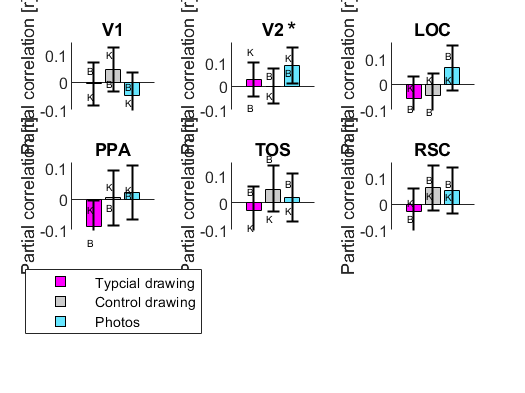

% preparation
cfg.partial_cor = true;
cfg.plotting = true;
cfg.plot_rdm = false;
cfg.predictor_RDMs = {'typical_late', 'control_late', 'photos_late'};
cfg.RDM_to_partial_out = cfg.predictor_RDMs;
cfg.rois_of_interest = {'V1', 'V2', 'LOC', 'PPA', ...
    'TOS', 'RSC'};
cfg.dnns = {'vgg16_imagenet'};
cfg.plot_type = 'bar';
cfg.show_single_cate = true;
cfg.permutation_test = true;
cfg.n_permutations = 10000;
cfg.permutation_type = 'row_col_shuffle_ref';
cfg.ISC_type = 'corrRep';
cfg.partial_correlation_type = 'pearson';

d = compare_roi_RDMs_to_predictor_RDMs(d, cfg);

Get inter-subject similarity on timecourses

% preparation
cfg.plotting = true;
cfg.rois = {'wV1.nii', 'wV2.nii', 'wLOC.nii',...
    'wPPA.nii', 'wTOS.nii', 'wRSC.nii',...
    'wmotorCortex.nii', 'wS1.nii', 'wauditoryCortex.nii'};

% get timecourses (average Voxels for each ROI)
cfg.n_voxels = 5;
funcROIs(cfg)

    Saved functional ROI for PPA to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\MNI_ROIs\func_ROIs\sub-001\PPA_funcROI.nii
    Saved functional ROI for TOS to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\MNI_ROIs\func_ROIs\sub-001\TOS_funcROI.nii
    Saved functional ROI for RSC to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\MNI_ROIs\func_ROIs\sub-001\RSC_funcROI.nii
    Saved functional ROI for LOC to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\MNI_ROIs\func_ROIs\sub-001\LOC_funcROI.nii
    Saved functional ROI for PPA to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\MNI_ROIs\func_ROIs\sub-002\PPA_funcROI.nii
    Saved functional ROI for TOS to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pe

cfg.skipIfExists = false;
cfg.smoothing = true; 
cfg.saveWholeBrain = false;
averageVoxelsInROI(cfg)

Subject: 1
Run: 1
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 2
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 3
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 4
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 5
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 6
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 7
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 8
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 9
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 10
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Subject: 2
Run: 1
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 2
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 3
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 4
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 5
Size bathroom: 79  95  79  75
Size kitchen: 79


% get ISC from timecourses
cfg.regressOutMean = true;
cfg.correlation_type = 'Pearson';
d = neural_timecourse_intersub_cor(d, cfg);

% get split-half reliability for ISC
d = splithalfReliabilityISC(d, cfg);

d = behResponseISRDM(cfg, d);

Compare ISC from drawings with timecourse ISC

 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of V1 bathroom is done
20% of permutations of V1 bathroom is done
30% of permutations of V1 bathroom is done
40% of permutations of V1 bathroom is done
50% of permutations of V1 bathroom is done
60% of permutations of V1 bathroom is done
70% of permutations of V1 bathroom is done
80% of permutations of V1 bathroom is done
90% of permutations of V1 bathroom is done
100% of permutations of V1 bathroom is done
Compare inter-subject RDM of V1 with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of V1 kitchen is done
20% of permutations of V1 kitchen is done
30% of permutations of V1 kitchen is done
40% of permutations of V1 kitchen is done
50% of permutations of V1 kitchen is done
60% of permutations of V1 kitchen is done
70% of permutations of V1 kitchen is done
80% of permutations of V1 kitchen is done
90% of permutations of V1 kitch

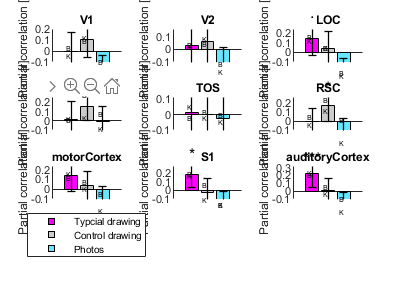

% preparation
cfg.partial_cor = 1;
cfg.plot_rdm = 0;
cfg.predictor_RDMs = {'typical_late', 'control_late', 'photos_late'};
cfg.RDM_to_partial_out = cfg.predictor_RDMs;
cfg.rois_of_interest = {'V1', 'V2', 'LOC', 'PPA', ...
    'TOS', 'RSC', 'motorCortex', 'S1', 'auditoryCortex'};
cfg.dnns = {'vgg16_imagenet'};
cfg.plot_type = 'bar';
cfg.show_single_cate = true;
cfg.permutation_test = true;
cfg.bootstrapping = false;
cfg.max_bootstrapping_n = 35;
cfg.n_bootstrapp_iterations = 1000;
cfg.bootstrapp_what = 'runs';
cfg.n_permutations = 100;
cfg.permutation_type = 'row_col_shuffle_pred';
cfg.ISC_type = 'timecourseRDM_concat';
cfg.partial_correlation_type = 'pearson';

d = compare_roi_RDMs_to_predictor_RDMs(d, cfg);

Get neural RDMs of single stimuli for each subject

% % preparations
% cfg.rois = {'wV1.nii', 'wV2.nii',...
%     'wLOC.nii', 'wRSC.nii',...
%     'wPPA.nii', 'wTOS.nii',...
%  'wS1.nii', 'wauditoryCortex.nii'};
% cfg.map = 't';
% 
% % run RDM based on simple correlations
% d.simgpleRDMresults = Copy_of_SimpleRDM(cfg.subNums, cfg.nTrials, cfg.map, cfg.rois)

% Get inter-subject similarity on single stimulus RDMs
% % preparation
% cfg.map = 't';
% cfg.plotting = false;
% 
% % run neural ISC script
% [d] = neural_intersub_cor(d, cfg)
% 

Compare ISC from drawings with neural ISC

% % preparation
% cfg.partial_cor = 1;
% cfg.plot_rdm = 0;
% cfg.RDM_to_partial_out = {'Typical Images vgg16_imagenet Late', 'Control Images vgg16_imagenet Late'};
% cfg.predictor_RDMs = {'typical_late', 'control_late'};
% cfg.rois_of_interest = {'wV1', 'wLOC', 'wPPA', ...
%     'wTOS', 'wRSC', 'wmotorCortex', 'wS1', 'wauditoryCortex'};
% cfg.dnns = {'vgg16_imagenet'};
% cfg.plot_type = 'bar';
% cfg.show_single_cate = 1;
% cfg.permutation_test = 1;
% cfg.n_permutations = 1000;
% cfg.permutation_type = 'row_col_shuffle_pred';
% 
% cfg.partial_correlation_type = 'pearson';
% 
% d = compare_roi_RDMs_to_predictor_RDMs(d, cfg);

End Message

% finished!
disp([ ...
    newline, ...
    '#########################', ...
    newline, ...
    '####### ALL DONE! #######', ...
    newline, ...
    '#########################', ...
    newline ...
    ]);